f = @(x,y) 80*exp(-1.6*x)*cos(4*x)-0.4*y

f = function_handle with value:
    @(x,y)80*exp(-1.6*x)*cos(4*x)-0.4*y


x0 = 0; xn = 4; n = 10; y0 = 0;
[y1, x1] = Euler(f,n,x0,xn,y0);
[y2, x2] = RK_2(f,n,x0,xn,y0);
[y3, x3] = RK_4(f,n,x0,xn,y0);
[x4, y4] = ode45(f,x0:(xn-x0)/n:xn,y0);
[x5, y5] = ode23(f,x0:(xn-x0)/n:xn,y0);
[x6, y6] = ode113(f,x0:(xn-x0)/n:xn,y0);
syms t
y_z = dsolve("Dy==80*exp(-1.6*t)*cos(4*t)-0.4*y","y(0) = 0",t);

y_x = double(subs(y_z,t,x1));
%error
error_el = double(abs(y1 - y_x))';
error_RK2 = double(abs(y2 - y_x))';
error_RK4 = double(abs(y3 - y_x))';
error_ode45 = double(abs(y4 - y_x'));
error_ode23 = double(abs(y5 - y_x'));
error_ode113 = double(abs(y6 - y_x'));
table(x4,error_el,error_RK2,error_RK4,error_ode45,error_ode23,error_ode113)

ans = 11×7 table
    x4     error_el    error_RK2    error_RK4    error_ode45    error_ode23    error_ode113
    ___    ________    _________    _________    ___________    ___________    ____________

      0          0            0            0              0              0               0 
    0.4     17.554       1.2528       5.0541      0.0091841      0.0027917       0.0022605 
    0.8      21.16       1.3764       2.5265      0.0006196      0.0017419       0.0020624 
    1.2     12.627       1.4505      0.61279       0.002516     0.00069633       0.0019121 
    1.6     8.9233      0.55194      0.90722     0.00026547     0.00075391       0.0016062 
      2     8.9284      0.41754       1.0589     0.00070474      0.0011753       0.0013592 
    2.4 

hold on
h = ezplot(y_z,[x0,xn]);
set(h,"Color","Red");
plot(x1,y1,"green")%euler
plot(x2,y2,"yellow")%RK2
plot(x3,y3,"magenta")%RK4
plot(x4,y4,"black")%ode45
plot(x5,y5,"blue")%ode23
plot(x6,y6,"cyan")%ode113
xlim auto
ylim auto
lgd = legend("Exact","Euler","RK2","RK4","ODE45","ODE23","ODE113")

lgd =   Legend (Exact, Euler, RK2, RK4, ODE45, ODE23, ODE113) with properties:

         String: {'Exact'  'Euler'  'RK2'  'RK4'  'ODE45'  'ODE23'  'ODE113'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7137 0.6500 0.1720 0.2500]
          Units: 'normalized'

  Show all properties


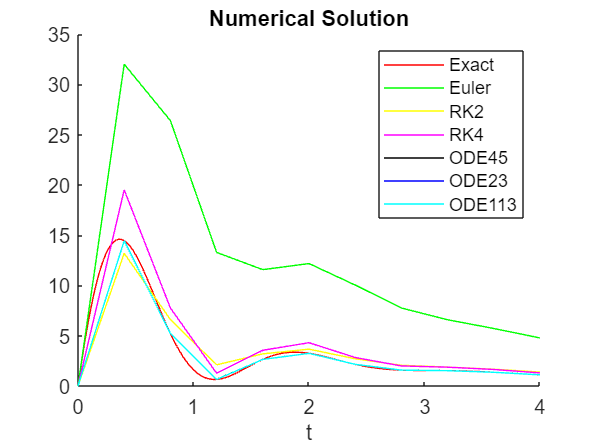

title("Numerical Solution")
hold off